close all
clear all
clc
%915614617

## Poles & Zeros Diagram

%Based on specs, find factors
b0=mod(1,2)+1

b0 = 2

b1=mod(4,3)+1

b1 = 2

b2=mod(6,4)+1

b2 = 3

b3=mod(1,5)+1

b3 = 2

b4=mod(7,6)+1

b4 = 2


%determine scaling?
scaling=2048*(b0+b1+b2+b3+b4)

scaling = 22528

%16 bit signed integer ranges from -32,768 to 32,767
if(scaling<32767) x=true
else x=false
end

x = logical
   1


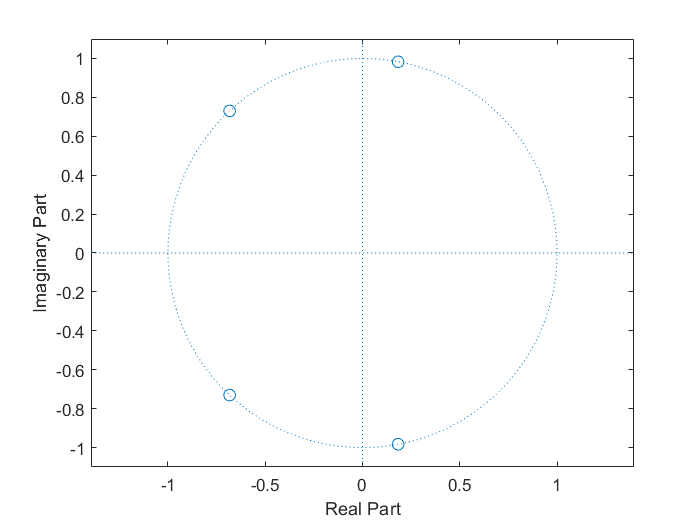


G=1; %gain of 1
coefficients=G*[b0,b1,b2,b3,b4];%z^4,z^3,z^2,z^1,z^0
zeros=roots(coefficients);%zeros
poles=[]; %poles

figure(1)
zplane(zeros,poles)

## Frequency Response plot

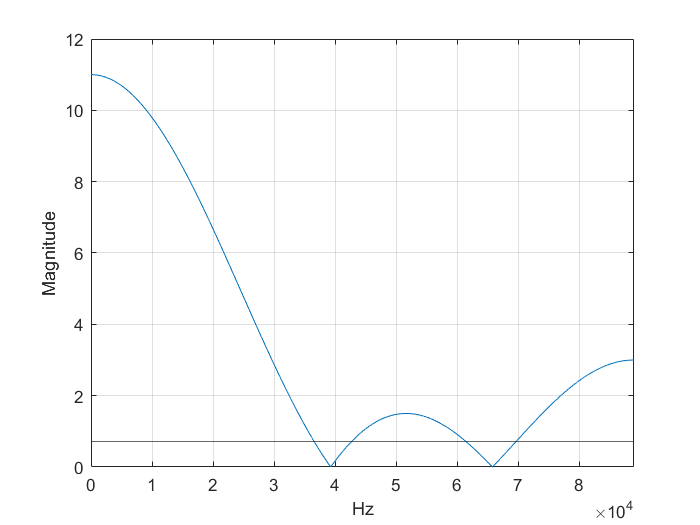

fs=178e3;    %sampling freq
ts=1/fs;    %sampling percent
[H,W]=freqz(coefficients,[1],fs);
W_0=(linspace(0,fs/2,length(W)))';

%plot freq response
figure(2)
plot(W_0,abs(H));
set(gca,'xlim',[0 fs/2]); grid on;
yline(.707);
xlabel('Hz');
ylabel('Magnitude');